# Threshold VAR

Tutorial file for showcasing  BVARs with threshold based regime switching

## Housekeeping

clear
close all
 
import threshold.*

## Convenience functions

The `extremesFunc` function compresses any number of samples (draws from the posterior) into two numbers - the minimum and the maximum.

percentiles = [10, 50, 90];

prctileFunc = @(x) prctile(x, percentiles, 2);

extremesFunc = @(x) [min(x, [], 2), max(x, [], 2)];

medianFunc = @(x) median(x, 2);

flatFunc = @(x) x(:, :);

defaultColors = get(0, "defaultAxesColorOrder");


## Number of Samples

numPresampled = 100;

## Prepare data and a reduced-form model

The properties specific to the threshold VARs are as follows:

**thresholdVarName  **– The variable serving as the threshold indicator for regime identification



estimStart = datex.q(1948,2);
estimEnd = datex.q(2016,4);
estimSpan = datex.span(estimStart, estimEnd);

meta = Meta( ...
    endogenousNames=["dl_y", "dl_cpi", "ir_tb", "stock_index"], ...
    thresholdName="stock_index", ...
    exogenousNames=[], ...
    order=4, ...
    intercept=true, ...
    estimationSpan=estimSpan, ...
    identificationHorizon=20 ...
);

## Specifying and loading input data

inputTbx = tablex.fromFile("data/thresholdData.csv");
dataH = DataHolder(meta, inputTbx);

## Reduced form model

### Minnesota dummies

please note that this model is using Minnesota dummies for the priors

minnesotaD = dummies.Minnesota();
minnesotaD

minnesotaD =   Minnesota with properties:

             Lambda: 0.1000
           LagDecay: 1
     Autoregression: 0.8000
          Exogenous: 0
    ExogenousLambda: 100


The estimator/model specific settings are the followings

**VarThreshold** – the prior variance of the threshold

**MaxDelay** – the maxium delay allowed for the threshold variable for regime identification

**ThresholdPropStd** – proposal standard deviation of the MH algorithm of the threshold draws

estimatorR = estimator.Threshold(meta);

modelR1 = ReducedForm( ...
    meta=meta ...
    , dataHolder=dataH ...
    , estimator=estimatorR ...
    , dummies={minnesotaD} ...
);


## Estimation/sampling of the reduced form model 


modelR1.Estimator.Settings

ans =   Threshold with properties:

              VarThreshold: 10
                  MaxDelay: 4
          ThresholdPropStd: 0.0316
                    Burnin: 0
        StabilityThreshold: Inf
    MaxNumUnstableAttempts: 1000
                 Exogenous: [4×1 logical]
            BlockExogenous: 0
            Autoregression: [4×1 double]
                   Lambda1: 0.1000
                   Lambda2: 0.5000
                   Lambda3: 1
                   Lambda4: [4×1 double]
                   Lambda5: 1.0000e-03


rng(0)
modelR1.initialize();
info5 = modelR1.presample(numPresampled);


 Presampling from posterior (Threshold) [100]
 ――――――――――――――――――――――――――――――――――――――――――――――――――  100% 





thresholds = cellfun(@(x) x.threshold, modelR1.Presampled);

disp("Mean threshold across all samples")

Mean threshold across all samples


mean(thresholds)

ans = 0.9274

## Running Unconditional forecast 

### Setting up the forecast range and run the forecast

fcastStart1 = datex.shift(modelR1.Meta.EstimationEnd, -230);
fcastEnd1 = datex.shift(modelR1.Meta.EstimationEnd, -180);
fcastSpan1 = datex.span(fcastStart1, fcastEnd1);

fcastTbx1 = modelR1.forecast(fcastSpan1, IncludeInitial=true);
fcastTbx1 = tablex.apply(fcastTbx1, prctileFunc); 
fcastPrctileTbx1 = tablex.flatten(fcastTbx1);

fcastStart2 = datex.shift(modelR1.Meta.EstimationEnd, -135);
fcastEnd2 = datex.shift(modelR1.Meta.EstimationEnd, -85);
fcastSpan2 = datex.span(fcastStart2, fcastEnd2);

fcastTbx2 = modelR1.forecast(fcastSpan2, IncludeInitial=true);
fcastTbx2 = tablex.apply(fcastTbx2, prctileFunc); 
fcastPrctileTbx2 = tablex.flatten(fcastTbx2);


### Visualize the unconditional forecast

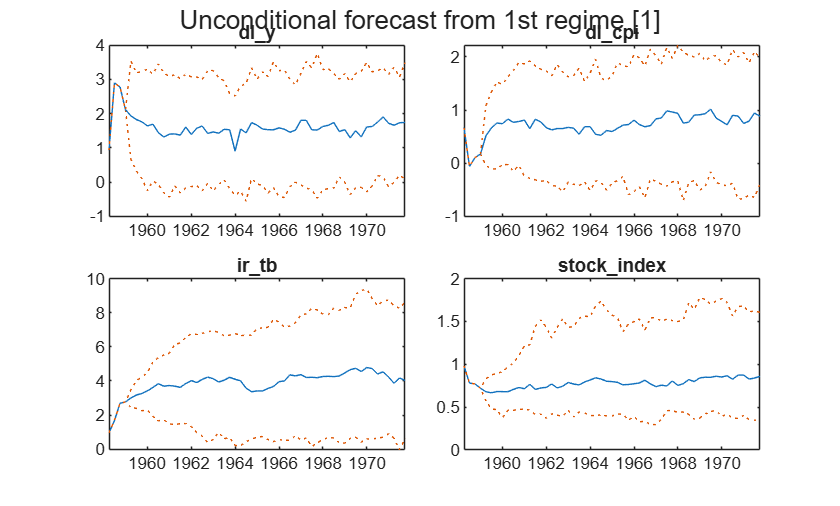

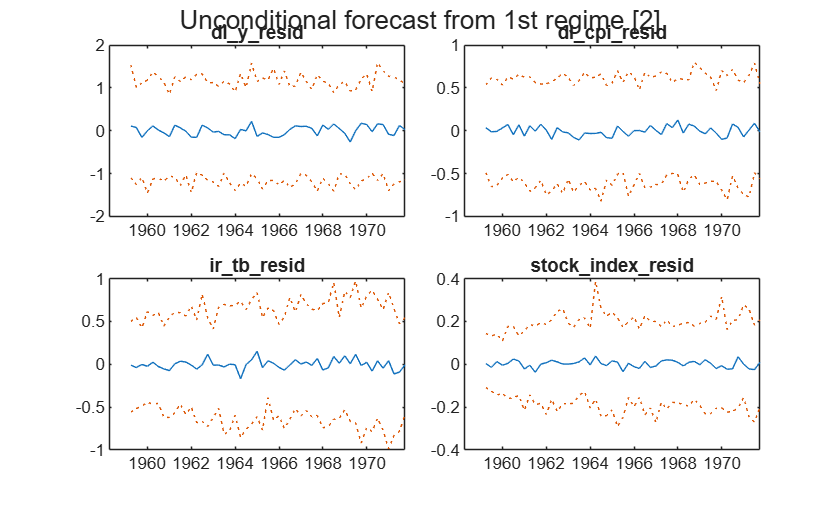

ans = 1×2 cell array
    {1×1 Figure}    {1×1 Figure}



chartpack.forecastPercentiles( ...
    fcastPrctileTbx1, modelR1, FigureTitle ="Unconditional forecast from 1st regime")

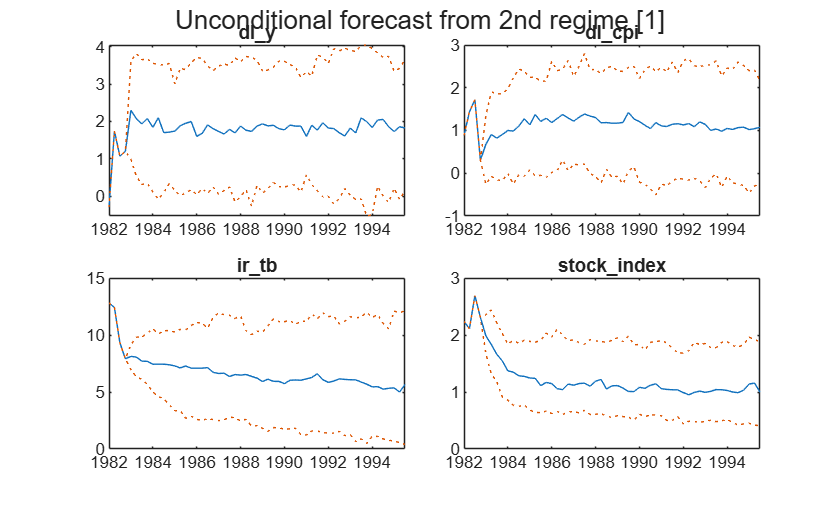

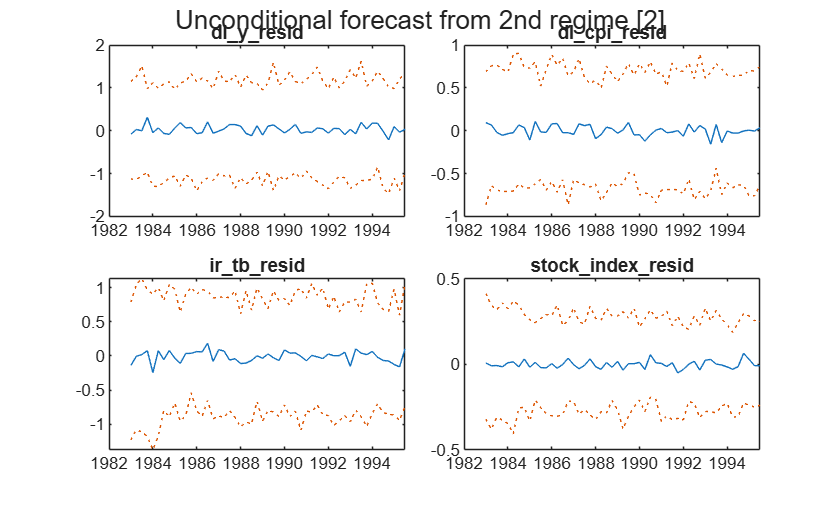



chartpack.forecastPercentiles( ...
    fcastPrctileTbx2, modelR1, FigureTitle ="Unconditional forecast from 2nd regime");